BASE_DIR='/Users/erik/Dropbox/Projects/Machine Learning/data/'

BASE_DIR = '/Users/erik/Dropbox/Projects/Machine Learning/data/'

m = 2;
b = 3;
y=zeros(1,150)

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


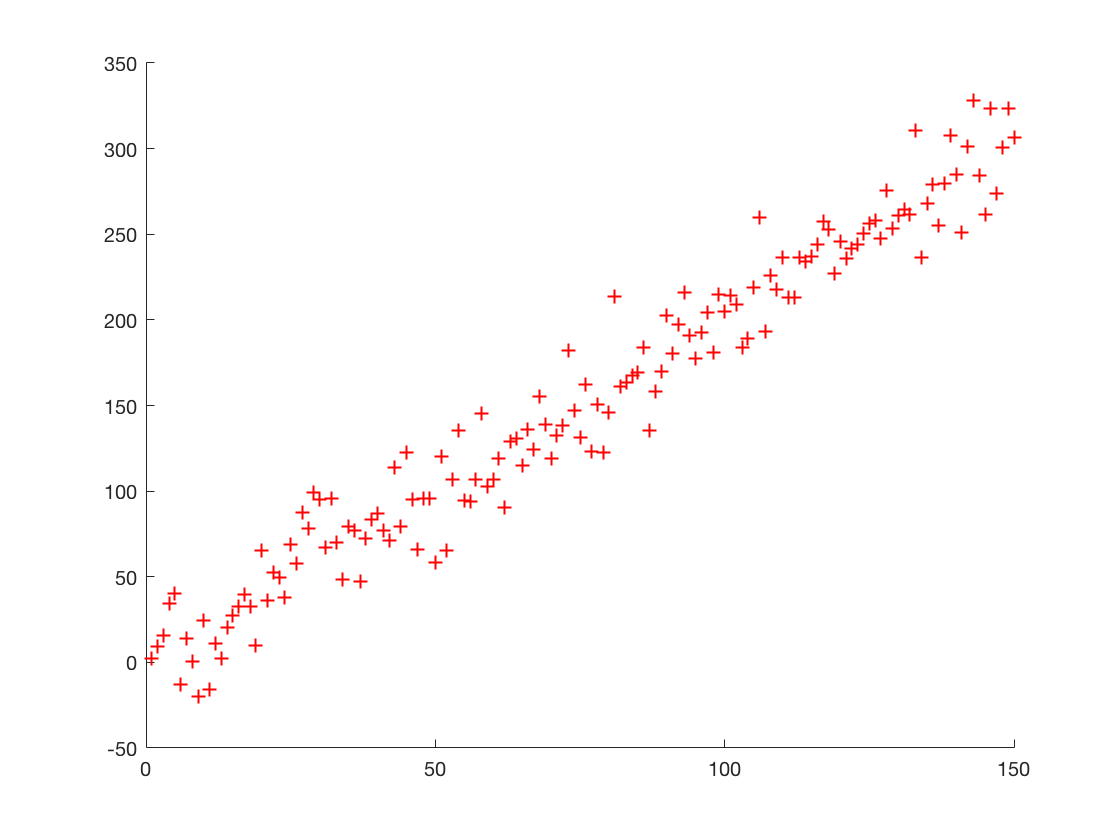

for x = 1:150
    mu=m*x+b;
    sigma = 20;
    
    % values are true + noise
    y(x) = normrnd(mu,sigma,1);
end

figure(1);
scatter(1:150,y,'r+');



X=horzcat((1:150)',y')

X =     1.0000    2.5501
    2.0000    9.2869
    3.0000   15.8320
    4.0000   34.1788
    5.0000   40.2102
    6.0000  -12.8631
    7.0000   14.1570
    8.0000    0.6695
    9.0000  -19.9167
   10.0000   24.2852


csvwrite(BASE_DIR+"values.csv",X)
